# Authors: Marta Barriendos & Ana Garcia Armada, Univesidad Carlos III de Madrid

# Combining OFDM with MIMO

## Introduction

This module is based on the implementation of a MIMO System, to understand its fundamentals and basic implementation. Then, the MIMO technique will be combined with OFDM, performing its abstraction in both, the frequency and time domain.

## Index

- MIMO Systems (Fundamentals and basic implementation)

- Combining MIMO with OFDM (Frequency domain abstraction)

- Combining MIMO with OFDM (Time domain simulation)

## 1. MIMO systems

A* MIMO system* (Multiple Input Multiple Output) is a technology used in wireless communication that consists of multiple antennas at both the transmitter and receiver, to improve communication performance. It enables better data throughput, reliability, and efficiency by leveraging spatial diversity and multiplexing.

There are two key aspects in a MIMO system to improve the performance: 

- **Spatial Diversity**: We can transmit the same data (symbol) through multiple paths (multiple antennas), which increases the likelihood that at least one signal arrives reliably, reducing the impact of fading.

- **Spatial Multiplexing**: We can transmit different data streams simultaneously over multiple paths or antennas, which boosts the data rate without needing additional bandwidth.

Therefore, MIMO is foundational for modern wireless standards like Wi-Fi, 4G LTE, and 5G, and probably will be for the new 6G standard, as it enhances capacity and coverage.

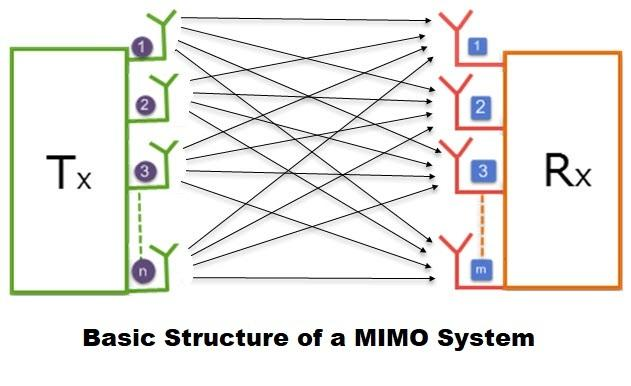

(Massive MIMO implementation for antenna diversity realization, *Research Gate*)

### Implementation of a basic MIMO system

We are going to start implementing a basic 2x2 MIMO system, that in the next section will be applied to an OFDM signal. 

The first step is to define the necesary parameters,starting by the number of transmit and receive antennas, which are 2 and 2 respectively, being these parameters ***nT*** and ***nR***. We can also define a new parameter ***m***, that is the number of spatial dimensions, in this case for the 2x2 implementation is not necessary, however, if we want to make an extension to more dimensions this could be useful. After this, we generate two identity matrix of 2x2, ***IR*** and ***IT***, using the function *eye*. On the other hand, ***x***, ***y*** and ***noise*** are vectors to hold the transmitted signal, received signal, and noise, repectively, being ***sigma_n*** the noise variance. Finally, since in this case we are only illustrating how to implement a basic MIMO system, we are going to transmit only 1 symbol.

nT = 2; % Number of transmit antennas
nR = 2; % Number of receive antennas
m = 2;  % Number of spatial directions (not used here but could be relevant for extensions)
IR = eye(nR); % Identity matrix for receive antennas
IT = eye(nT); % Identity matrix for transmit antennas
x = zeros(nT,1); % Initialize transmitted signal vector
y = zeros(nR,1); % Initialize received signal vector
noise = zeros(nR,1); % Initialize noise vector
sigma_n = 1e-1; % Noise variance

Once we have all the parameters defined, we start generating our channel matrix, ***Hw***, modeled as a 2×2 matrix with independent Rayleigh fading coefficients. Each element of ***Hw*** is a complex Gaussian random variable with mean 0 and variance 1. ***Randn(nR, nT)*** generates real and imaginary parts, scaled by ***1/sqrt(2)*** to match Rayleigh fading.

%Generate Channel Matrix (Hw)
Hw = 1./sqrt(2) .* (randn(nR, nT) + j .* randn(nR, nT));

This channel is like the one presented in the image below (***Hk***), we have a channel matrix instead of a vector because each one of the four possible paths between the antennas has a different channel response modeled as coefficients in our matrix ***Hw***.

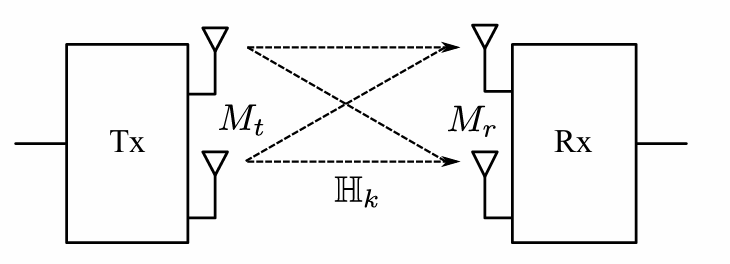 

The next step is to generate the symbols that we are going to transmit through the channel, ***x***, creating a complex QAM symbol for each transmission antenna (using for ***i*** and ***q*** the transmission dimension, ***nT***)

%Generate QAM Transmit Symbols (x)
i = sign(rand(nT,1) - 0.5); % Generate random +1 or -1 for real part
q = sign(rand(nT,1) - 0.5); % Generate random +1 or -1 for imaginary part
x = i + j * q;               % Complex symbol vector (BPSK per component)

Noise is added to the received signal. Each element of ***noise*** is a complex Gaussian random variable with mean 0 and variance ***sigma_n / 2*** ***, ***that we had previosly defined in the first section, therefore the variance of the total noise is ***sigma_n***. It's important to notice that for the noise we are going to use the receiver dimensions, ***nR***, since the noise will be applied to the received signal.

%Generate Noise
noise = sqrt(sigma_n / 2) * (randn(nR, 1) + j * randn(nR, 1));

Finally, we receive the transmitted symbols through the channel, we will have two different results, the one received by the first receiver antenna, and the one received by the second receive antenna, therefore ***y***, that is the received signal vector after the transmitted signal ***x*** passes through the channel matix ***Hw*** and is affected by noise, will have two components, the one of the first antenna, and the one of the second antenna. 

%Received Signal (y)
y = Hw * x + noise;

At this point, the receiver already has the symbols, but contaminated by noise. Now, we need to recover these symbols, compensating the effect that the channel has introduced to them. Thus, we just need to apply the pseudo-inverse of the channel matrix (***pinv(Hw)***) to the receive signal (***y***) with the product, and ***z*** will be the recovered signal vector after the ZF equalization. 

However, it's important to reflect that, since we are contaminating our signal with noise, but the ZF only compensates the effect of the channel, the recovered symbols won't be exactly the original ones, since we aren't removing the effect of the noise, which is not negligible, as we will see in the representation. 

%Zero-Forcing (ZF) Receiver
G_ZF = pinv(Hw); % Pseudo-inverse of Hw for ZF equalization
z = G_ZF * y;    % Recovered signal after ZF equalization

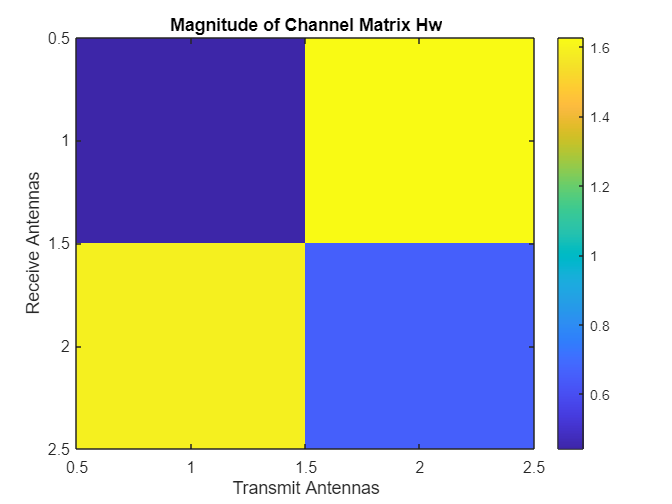

% Plot the magnitude of the channel matrix Hw
figure;
imagesc(abs(Hw));  % Plot the magnitude of the channel matrix
colorbar;  % Add color bar to represent values
title('Magnitude of Channel Matrix Hw');
xlabel('Transmit Antennas');
ylabel('Receive Antennas');

Finally, we can see the original symbols transmitted ***x***, the received ones ***y***, and the recovered ones ***z***, in the next graph. As we have explained before, we can noticie how the recovered symbols (in green) are not exacty the transmitted ones (in blue), because we aren't compensating the noise, only the channel, with the Zero Forcing implementation. However, the recovered symbols are near enough to the real transmitted symbols to estimate using a threshold or any other technique the real transmitted symbols, using these recovered ones. 

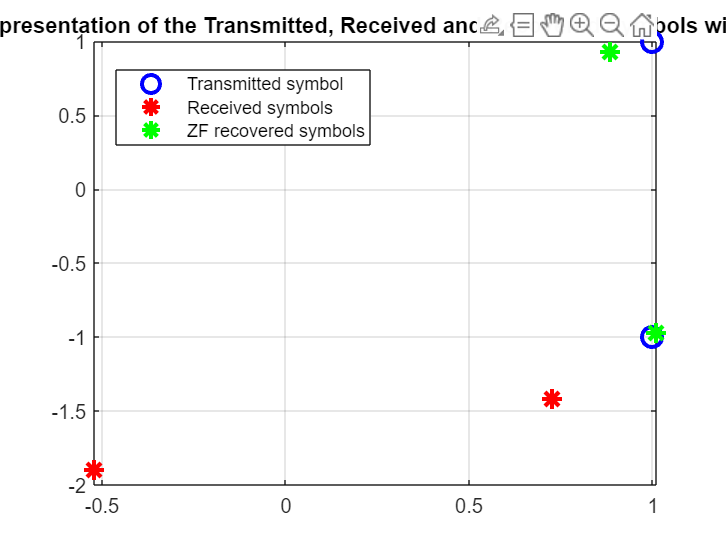

plot(x, 'ob', 'MarkerSize', 10, 'LineWidth', 2)    % Transmitted symbols (circles)
hold on
plot(y, '*r', 'MarkerSize', 10, 'LineWidth', 2)   % Received symbols (red stars)
plot(z, '*g', 'MarkerSize', 10, 'LineWidth', 2)   % ZF-recovered symbols (green stars)
legend('Transmitted symbol', 'Received symbols','ZF recovered symbols')
grid on;
title("Representation of the Transmitted, Received and Recovered Symbols with ZF")

## 2. Combining MIMO with OFDM (Frequency Domain Abstraction)

In the code above, a **flat-fading channel model** was being used. This means that the channel behaves the same way across all frequencies of the transmitted signal. In other words, the channel does not introduce different distortions at different frequencies; the entire signal experiences the same type of **fading** and **delay**.

However, this type of channel model is only valid in two situations: 

- **The signal bandwidth is small** compared to the coherence bandwidth of the channel. This implies that all frequencies within the signal are correlated and affected in the same way.

- **There is no significant multi-path delay spread**. This means that reflections and multi-path signals arrive at the receiver within a short enough interval that the channel does not cause frequency dispersion.

Tha's why we represent the Rayleigh channel with a random matrix **Hw** of dimensions ***nR ***x*** nT***, which reflects the fading gain for each combination of transmit and receive antennas. However, this assumes that the channel remains constant across the entire frequency range of the signal, which as we have said before, usually is not the case. 

In the majority of the cases, the channel experiences **frequency dispersion** due to multiple paths with significant delays. This causes different parts of the signal spectrum to be affected differently, leading to what’s known as a **frequency-selective channel:**

- The channel response varies across the frequency band of the signal.

- Different frequency components of the signal can experience different gains and phases, leading to **Inter-Symbol Interference (ISI)** at the receiver.

To handle these effects, we need to use OFDM with MIMO, because thanks to the use of OFDM, we divide the signal into multiple subcarriers, and therefore, for each subcarrier, we can approximate the channel response as flat. 

When we combine **MIMO (Multiple Input Multiple Output)** with **OFDM**, we get the benefits of both:

- **OFDM** converts a frequency-selective channel into multiple frequency-flat subchannels, which simplifies equalization at the receiver.

- **MIMO** allows us to use multiple antennas to improve channel capacity or transmission robustness through techniques like **Spatial Multiplexing** (to increase data rate) or **Spatial Diversity** (to improve reliability).

**MIMO-OFDM Implementation**

In the next section we are going to implement a MIMO-OFDM system, the data flow is organized as follows:

- The data signal is divided into multiple subcarriers (usually via a **Fast Fourier Transform (FFT)**).

- On each subcarrier, a combination of signals from different transmit antennas is sent (usually modulated in QAM or PSK).

- Each subcarrier experiences a flat-fading channel because of the narrow bandwidth.

- At the receiver, an FFT is applied to recover the signals on each subcarrier, and then an equalization scheme like **Zero-Forcing (ZF)** or **Minimum Mean Square Error (MMSE)** is used on each subcarrier for each receive antenna.

We have implemented a MIMO system using directly the frequency response of the channel. This means that as a first approach, we have made a frequency abstraction,  considering that the entire process enclosed in brackets (in the image below), including OFDM modulation and transmission through the channel, can be represented by a frequency response ***Hk.*** This will allow us to conduct a simpler initial analysis.

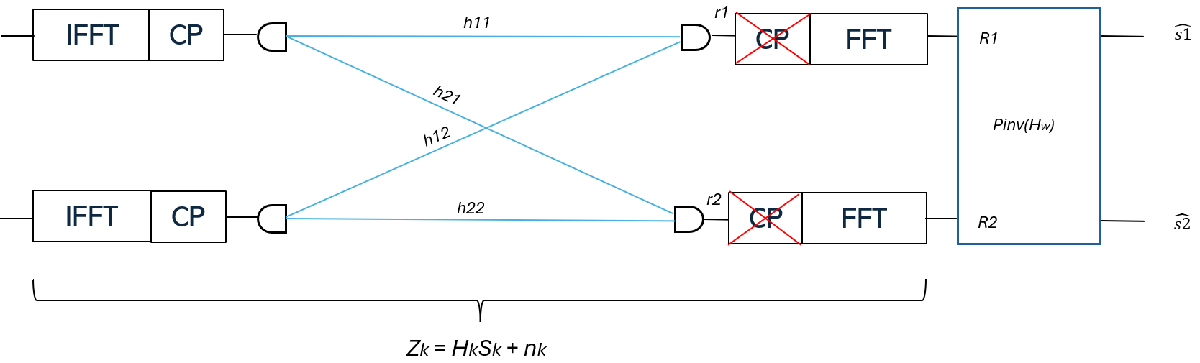

We start defining the necessary parameters, correponding to the number of transmit and receive antennas (***nT*** and ***nR***), the number of subcarriers in each OFDM symbol (***num_subcarriers***) and the noise variance (***signma_n***).

% Parameters
nT = 2;                 % Number of transmit antennas
nR = 2;                 % Number of receive antennas
num_subcarriers = 2048; % Number of subcarriers in the OFDM symbol
sigma_n = 1e-3;         % Noise variance

Then, we are going to generate QPSK symbols for each subcarrier and each antenna, where ***x_ant1*** and ***x_ant2*** are vectors of 2048 QPSK symbols each, representing the transmitted data for antenna 1 and antenna 2, respectively. Therefore, in MIMO-OFDM both antennas transmit on the same assigned frequency band its symbols. This means that for each subcarrier of an OFDM signal, both antennas will be transmitting on the same subcarrier or frequency in parallel. For example, if the first subcarrier corresponds to 5 MHz, both antennas will transmit on that subcarrier at 5 MHz simultaneously, although each antenna transmits a different symbol which allows the receiver to take advantage of spatial multiplexing to recover information using MIMO. 

% Generate QPSK symbols for each subcarrier and each antenna
% We assume each subcarrier has one QPSK symbol for each transmit antenna
x_ant1 = (sign(rand(num_subcarriers, 1) - 0.5) + 1j * sign(rand(num_subcarriers, 1) - 0.5)) / sqrt(2);
x_ant2 = (sign(rand(num_subcarriers, 1) - 0.5) + 1j * sign(rand(num_subcarriers, 1) - 0.5)) / sqrt(2);

We initialize the vectors where we will store the transmitted symbols

% Initialize vectors to store transmitted and received symbols for each subcarrier
received_ant1 = zeros(num_subcarriers, 1);
received_ant2 = zeros(num_subcarriers, 1);
y = zeros(2,num_subcarriers);

As next step, we assume a fixed MIMO channel matrix ***Hw ***for each subcarrier. We assume different channel matrices for all subcarriers in this example.

The last step consist of making a loop over all these subcarriers. First, for each subcarrier (indexed by ***k***), we form the transmitted symbol vector ***x*** with the symbols for that subcarrier on each antenna. Then, we add some noise to the received signal for each subcarrier, simulating a real scenario. The received signal ***y*** is computed using the frequency channel matrix ***Hw. ***Finally, to recover the transmitted symbols, we appy a Zero-Forcing (ZF) equalizer to ***y*** using the pseudo-inverse of ***Hw*** to retrieve the transmitted symbols, producing ***z, ***where the first component corresponds to the symbol transmitted by the first antenna, and the second one corresponds to the symbol transmitted by the second antenna. The recovered symbols*** z*** are stored in ***received_ant1*** and ***received_ant2*** for each subcarrier.

% Loop over each subcarrier
for k = 1:num_subcarriers

    %One channel per subcarrier
    Hw = 1 / sqrt(2) * (randn(nR, nT) + 1j * randn(nR, nT));

    % Construct the transmitted symbol vector for subcarrier k
    x = [x_ant1(k); x_ant2(k)];
    
    % Add noise for this subcarrier
    noise = sqrt(sigma_n / 2) * (randn(nR, 1) + 1j * randn(nR, 1));
    
    % Transmit through the channel (frequency domain channel response)
    y(:,k) = Hw * x + noise; % Received signal with noise
    
    % Zero-Forcing (ZF) Receiver
    G_ZF = pinv(Hw); % Compute the pseudo-inverse of Hw for ZF equalization
    z = G_ZF * y(:,k);    % Recovered signal after ZF equalization
    
    % Store the recovered signals for each antenna
    received_ant1(k) = z(1); % Signal recovered for antenna 1
    received_ant2(k) = z(2); % Signal recovered for antenna 2
end

Finally, we plot the transmitted against received and recovered symbols for each antenna, to visualize how well the ZF equalizer retrieves the transmitted QPSK symbols.

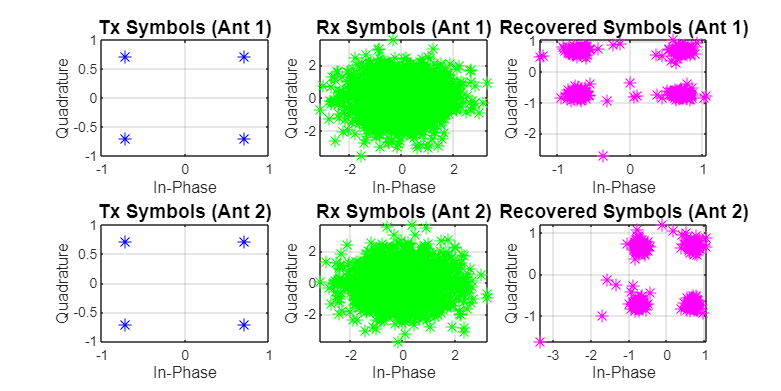

% Plot transmitted vs. received symbols for each antenna
figure('Position', [100, 100, 1200, 600]); 

% Transmitted Symbols for Antenna 1
subplot(2, 3, 1);
plot(real(x_ant1), imag(x_ant1), '*b', 'MarkerSize', 8); 
title('Tx Symbols (Ant 1)', 'FontSize', 12); 
xlabel('In-Phase', 'FontSize', 10); 
ylabel('Quadrature', 'FontSize', 10);
grid on;

% Received Symbols for Antenna 1
subplot(2, 3, 2);
plot(real(y(1,:)), imag(y(1,:)), '*g', 'MarkerSize', 8); 
title('Rx Symbols (Ant 1)', 'FontSize', 12);
xlabel('In-Phase', 'FontSize', 10);
ylabel('Quadrature', 'FontSize', 10);
grid on;
axis tight;

% Recovered Symbols for Antenna 1
subplot(2, 3, 3);
plot(real(received_ant1), imag(received_ant1), '*m', 'MarkerSize', 8); 
title('Recovered Symbols (Ant 1)', 'FontSize', 12);
xlabel('In-Phase', 'FontSize', 10);
ylabel('Quadrature', 'FontSize', 10);
grid on;
axis tight;

% Transmitted Symbols for Antenna 2
subplot(2, 3, 4);
plot(real(x_ant2), imag(x_ant2), '*b', 'MarkerSize', 8); 
title('Tx Symbols (Ant 2)', 'FontSize', 12);
xlabel('In-Phase', 'FontSize', 10);
ylabel('Quadrature', 'FontSize', 10);
grid on;

% Received Symbols for Antenna 2
subplot(2, 3, 5);
plot(real(y(2,:)), imag(y(2,:)), '*g', 'MarkerSize', 8); 
title('Rx Symbols (Ant 2)', 'FontSize', 12);
xlabel('In-Phase', 'FontSize', 10);
ylabel('Quadrature', 'FontSize', 10);
grid on;
axis tight;

% Recovered Symbols for Antenna 2
subplot(2, 3, 6);
plot(real(received_ant2), imag(received_ant2), '*m', 'MarkerSize', 8); 
title('Recovered Symbols (Ant 2)', 'FontSize', 12);
xlabel('In-Phase', 'FontSize', 10);
ylabel('Quadrature', 'FontSize', 10);
grid on;
axis tight;

As we can see in the previous graphs, the first row corresponds to the QPSK symbols transmitted in each subcarrier by the first antenna, and the second row by the second one. For both antennas, the received symbols are contaminated by noise, and therefore the constellation (green) is a noisy QPSK, it's even difficult to distinguish if that's really a QPSK modulation. However, in the last column, we can see the recovered symbols using the ZF equalizer, where clearly we can see in both cases a clearer QPSK constellation, although obviously is not perfect (like the transmitted one) since we aren't compensating the effect of the noise, only the channel effect. 

## 3. Combining MIMO with OFDM (Time Domain Simulation)

In this last section, once we have undestood the previous frequency abstraction, we are going to make a complete implementation of MIMO with OFDM in the time domain. Therefore, in this case, if we look again at the first scheme presented above for the frequency abstraction, now we are going to implement the complete process of, creating some symbols, modulating them as an OFDM signal, tranmitting them through the channel, and recovering the original constelation. 

The first step consists of defining the different parameters needed:

% Parameters
nT = 2;                 % Number of transmit antennas
nR = 2;                 % Number of receive antennas
num_subcarriers = 2048; % Number of subcarriers in the OFDM symbol
sigma_n = 2e-6;         % Noise variance
rng(5);                 %seed to always get the same result

Let's start **modeling the channel** in the time domain, defining the fixed MIMO channel matrix with 2 taps for each channel:

- ***h11, h12***: Channels from transmitter antennas 1 and 2 to receiver antenna 1.

- ***h21, h22***: Channels from transmitter antennas 1 and 2 to receiver antenna 2.

h11 = 1 / sqrt(2) * (randn(1, 2) + 1j * randn(1, 2));
h12 = 1 / sqrt(2) * (randn(1, 2) + 1j * randn(1, 2));
h21 = 1 / sqrt(2) * (randn(1, 2) + 1j * randn(1, 2));
h22 = 1 / sqrt(2) * (randn(1, 2) + 1j * randn(1, 2));

Then, we construct the **OFDM Signal: **

- We generate QPSK symbols for 2048 subcarriers for each transmit antenna.

- Apply **IFFT** to convert the signals to the time domain.

- Add a **cyclic prefix** to each OFDM symbol.

% Generate QPSK symbols
x_ant1 = (sign(rand(num_subcarriers, 1) - 0.5) + 1j * sign(rand(num_subcarriers, 1) - 0.5)) / sqrt(2);
x_ant2 = (sign(rand(num_subcarriers, 1) - 0.5) + 1j * sign(rand(num_subcarriers, 1) - 0.5)) / sqrt(2);

% Convert to time domain using IFFT
ofdm1 = ifft(x_ant1);
ofdm2 = ifft(x_ant2);

% Add cyclic prefix (assuming prefix length = 16 samples)
cp_length = 16;
ofdm1_cp = [ofdm1(end - cp_length + 1:end); ofdm1];
ofdm2_cp = [ofdm2(end - cp_length + 1:end); ofdm2];

Let's plot ***ofdm1_cp*** and ***ofdm2_cp*** to see that we have now OFDM signals, that we are going to send through the corresponding channel: 

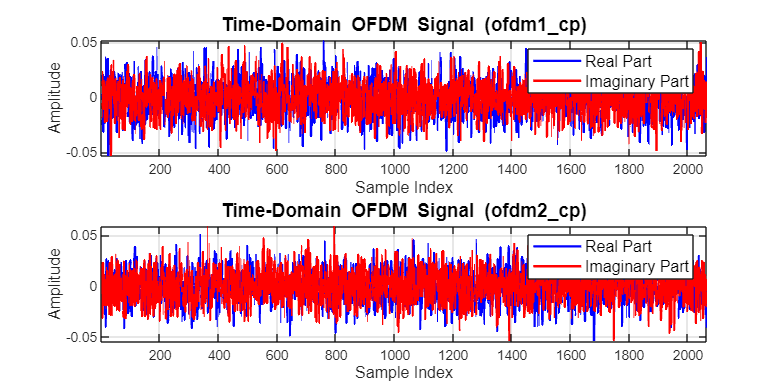

% Plot the time-domain OFDM signals
figure('Position', [100, 100, 1200, 600]);

% Plot OFDM1 with cyclic prefix
subplot(2, 1, 1);
plot(real(ofdm1_cp), 'b', 'LineWidth', 1.5); % Real part
hold on;
plot(imag(ofdm1_cp), 'r', 'LineWidth', 1.5); % Imaginary part
title('Time-Domain OFDM Signal (ofdm1\_cp)', 'FontSize', 12);
xlabel('Sample Index', 'FontSize', 10);
ylabel('Amplitude', 'FontSize', 10);
legend('Real Part', 'Imaginary Part', 'FontSize', 10);
grid on;
axis tight;

% Plot OFDM2 with cyclic prefix
subplot(2, 1, 2);
plot(real(ofdm2_cp), 'b', 'LineWidth', 1.5); % Real part
hold on;
plot(imag(ofdm2_cp), 'r', 'LineWidth', 1.5); % Imaginary part
title('Time-Domain OFDM Signal (ofdm2\_cp)', 'FontSize', 12);
xlabel('Sample Index', 'FontSize', 10);
ylabel('Amplitude', 'FontSize', 10);
legend('Real Part', 'Imaginary Part', 'FontSize', 10);
grid on;
axis tight;

In the previous graphs, we can clearly see how we are transmitting one OFDM symbol, of 2048 subcarriers plus 16 samples of cyclic prefix, and obviously it correponds to the OFDM signal we wanted to generate. 

Now, we can already **transmit **the OFDM signal **through the MIMO Channel.**

Each received sample is a combination of the transmitted samples convolved with the corresponding channel taps. Also, we need to add the noise to each received sample:

% Initialize received signals
% Create shifted versions of the OFDM signals
ofdm1_shifted = [0; ofdm1_cp(1:end-1)]; % ofdm1 (n-1)
ofdm2_shifted = [0; ofdm2_cp(1:end-1)]; % ofdm2 (n-1)

% Compute received signals using the convolution with the channel response
r1 = ofdm1_cp .* h11(1) + ofdm1_shifted .* h11(2) + ...
     ofdm2_cp .* h12(1) + ofdm2_shifted .* h12(2) + ...
     sqrt(sigma_n / 2) * (randn(size(ofdm1_cp)) + 1j * randn(size(ofdm1_cp)));

r2 = ofdm1_cp .* h21(1) + ofdm1_shifted .* h21(2) + ...
     ofdm2_cp .* h22(1) + ofdm2_shifted .* h22(2) + ...
     sqrt(sigma_n / 2) * (randn(size(ofdm2_cp)) + 1j * randn(size(ofdm2_cp)));


Finally, we just need to do the** Receiver Processing **to recover the original symbols, and get a QPSK constellation, applying the next steps: 

- Remove the cyclic prefix.

- Apply **FFT** to convert the received signal back to the frequency domain.

- Use the channel matrix H to equalize the received signals via **Zero-Forcing**.

% Remove cyclic prefix
r1_no_cp = r1(cp_length + 1:end);
r2_no_cp = r2(cp_length + 1:end);

% Apply FFT
R1 = fft(r1_no_cp);
R2 = fft(r2_no_cp);

% Construct the frequency-domain channel matrix H for each subcarrier
received_ant1 = zeros(num_subcarriers, 1);
received_ant2 = zeros(num_subcarriers, 1);

for k = 1:num_subcarriers
    
    % Frequency-domain channel coefficients
    H11 = fft(h11, num_subcarriers);
    H12 = fft(h12, num_subcarriers);
    H21 = fft(h21, num_subcarriers);
    H22 = fft(h22, num_subcarriers);
    
    H = [H11(k), H12(k); H21(k), H22(k)];
    
    % Received vector for subcarrier k
    Y = [R1(k); R2(k)];
    
    % Zero-Forcing equalization
    G_ZF = pinv(H); % Pseudo-inverse
    Z = G_ZF * Y;   % Recovered symbols
    
    % Store the results
    received_ant1(k) = Z(1);
    received_ant2(k) = Z(2);
end

Finally, we will have in the signals*** received_ant1*** and ***received_ant2*** the recovered symbols transmitted by the first antenna, and the second antenna, respectively. But, in order to verify that we have properly recovered the original symbols, we're going to plot the constellation, and verify how as we were expecting, we get a QPSK constellation, although it obvioulsy has some noise, since as in previous cases, we are compensating the channel with the ZF but not the corresponding noise. 

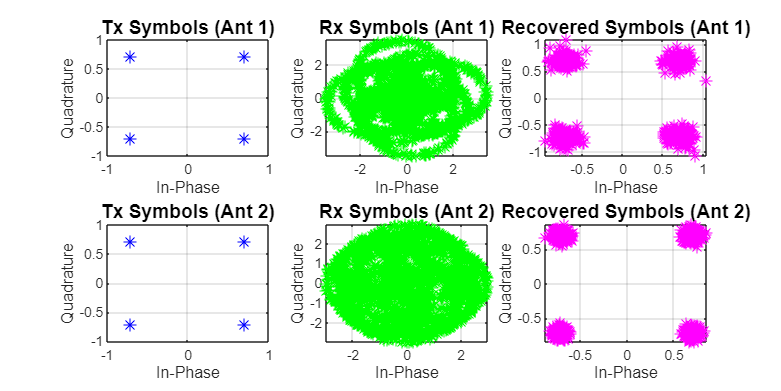


% Plot transmitted vs. received symbols for each antenna
figure('Position', [100, 100, 1200, 600]); 

% Transmitted Symbols for Antenna 1
subplot(2, 3, 1);
plot(real(x_ant1), imag(x_ant1), '*b', 'MarkerSize', 8); 
title('Tx Symbols (Ant 1)', 'FontSize', 12);
xlabel('In-Phase', 'FontSize', 10);
ylabel('Quadrature', 'FontSize', 10);
grid on;

% Received Symbols for Antenna 1
subplot(2, 3, 2);
plot(real(R1), imag(R1), '*g', 'MarkerSize', 8); % Received signal from FFT
title('Rx Symbols (Ant 1)', 'FontSize', 12);
xlabel('In-Phase', 'FontSize', 10);
ylabel('Quadrature', 'FontSize', 10);
grid on;
axis tight;

% Recovered Symbols for Antenna 1
subplot(2, 3, 3);
plot(real(received_ant1), imag(received_ant1), '*m', 'MarkerSize', 8); % Symbols after ZF equalization
title('Recovered Symbols (Ant 1)', 'FontSize', 12);
xlabel('In-Phase', 'FontSize', 10);
ylabel('Quadrature', 'FontSize', 10);
grid on;
axis tight;

% Transmitted Symbols for Antenna 2
subplot(2, 3, 4);
plot(real(x_ant2), imag(x_ant2), '*b', 'MarkerSize', 8); % Transmitted symbols
title('Tx Symbols (Ant 2)', 'FontSize', 12);
xlabel('In-Phase', 'FontSize', 10);
ylabel('Quadrature', 'FontSize', 10);
grid on;

% Received Symbols for Antenna 2
subplot(2, 3, 5);
plot(real(R2), imag(R2), '*g', 'MarkerSize', 8); % Received signal from FFT
title('Rx Symbols (Ant 2)', 'FontSize', 12);
xlabel('In-Phase', 'FontSize', 10);
ylabel('Quadrature', 'FontSize', 10);
grid on;
axis tight;

% Recovered Symbols for Antenna 2
subplot(2, 3, 6);
plot(real(received_ant2), imag(received_ant2), '*m', 'MarkerSize', 8); % Symbols after ZF equalization
title('Recovered Symbols (Ant 2)', 'FontSize', 12);
xlabel('In-Phase', 'FontSize', 10);
ylabel('Quadrature', 'FontSize', 10);
grid on;
axis tight;

As we explained before, with the graphs above, we can clearly see how we're recovering the QPSK constellation, although contaminated by noise, as we were expecting, since we're only compensating the channel with the ZF, but not the noise.